load data

gm = cell(4,1);
for i = 1:4
    gm{i} = fitgmdist(x{i}(4,:)',2); %,...
%                 'CovarianceType',Sigma{j},...
%                 'SharedCovariance',SharedCovariance{m},...
%                 'RegularizationValue',RegularizationValue,...
%                 'Options',options);
end

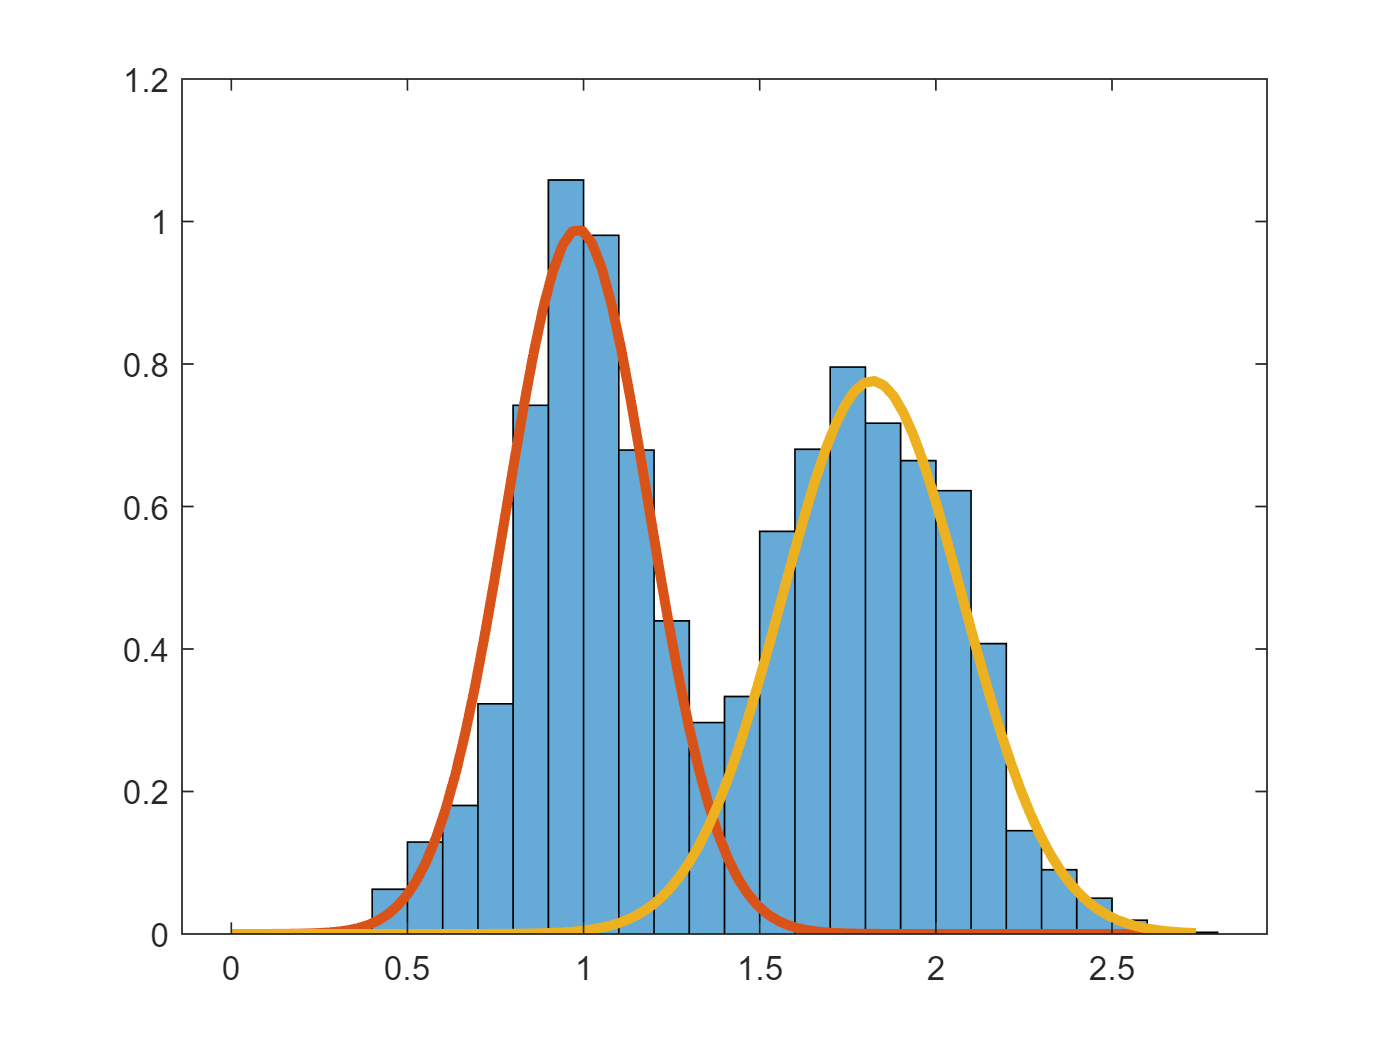

figure
z_1 = x{1}(4,:);
h = histogram(z_1);
h.Normalization = "pdf";
hold on
t = linspace(min(z_1),max(z_1));% разбивает пространство данных между максмум и мин на 100 равных шагов
plot(t,pdf('Normal',t, gm{1}.mu(1),sqrt(gm{1}.Sigma(1)))/2,"LineWidth",3);
plot(t,pdf('Normal',t, gm{1}.mu(2),sqrt(gm{1}.Sigma(2)))/2,"LineWidth",3);

h = chi2gof(z_1,'CDF',gm{1})

Error using chi2gof (line 216)
The 'cdf' value must be a ProbDist object, a function handle, or a cell array containing a function handle.

z_2 = x{2}(4,:);
h = histogram(z_2);

z_3 = x{3}(4,:);
h = histogram(z_3);

z_4 = x{4}(4,:);
h = histogram(z_4);